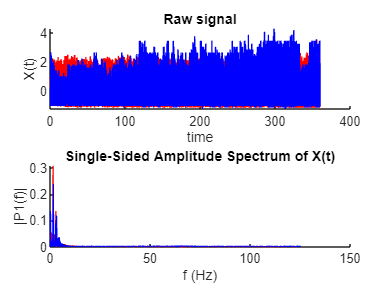

PPG=xlsread("F:\IITM\Mtech 2_sem\Advanced_BME_lab\Heart rate varibility.xlsx"'); 
PPG_M=PPG(:,1); %%MOTHER
PPG_F=PPG(:,2); %%Normal
fs=250;                       
X1 =normalize(PPG_M);
X2 =normalize(PPG_F); 
[n1,n2]=size(X1);
[n1,n2]=size(X2);
T=1/fs; 
L=n1;
t=(0:L-1)*T;
figure(1);
subplot(2,1,1);
hold on 
plot(t,X1,'r') %%Pregnant women
plot(t,X2,'b') %%non-pregnant women
title('Raw signal')
xlabel('time')
ylabel('X(t)')
 
 
Y = fft(X1);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);   
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
 
Y1 = fft(X2);
P2f = abs(Y1/L);
P1f = P2f(1:L/2+1);
P1f(2:end-1) = 2*P1f(2:end-1);
ff = fs*(0:(L/2))/L;
subplot(2,1,2);
hold on;
plot(f,P1,'r') %%Mother
plot(ff,P1f,'b') %%Normal
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel("|P1(f)|")

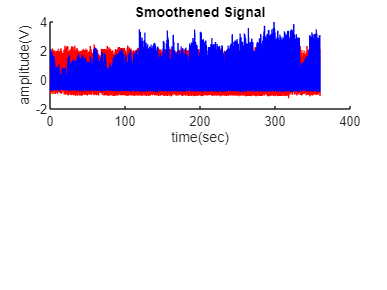


%%Smoothening:
preg =sgolayfilt(X1,2,31);
nonpreg= sgolayfilt(X2,2,31);
figure(2);
subplot(2,1,1);
hold on;
plot(t, preg,'r')
plot(t, nonpreg,'b')
title('Smoothened Signal');
xlabel('time(sec)')
ylabel('amplitude(V)')

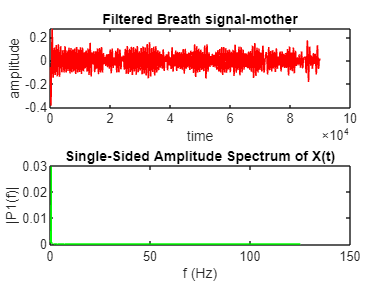



%% Bandpassed signal of mother
W1=0.2/(fs/2);
W2=0.4/(fs/2);
[b,a]=butter(2,[W1 W2]);
y1 = filtfilt(b,a,X1); %%preg PPG
y2 = filtfilt(b,a,X2); %%non-preg PPG

N2=length(y1);
t1=[0:N2-1]/fs;

figure(3);
subplot(2,1,1);
plot(y1,'r'); %%preg
title('Filtered Breath signal-mother')             
xlabel('time')
ylabel('amplitude')
Y1 = fft(y1);
P21 = abs(Y1/L);    
P11 = P21(1:L/2+1);
P11(2:end-1) = 2*P11(2:end-1);
f1 = fs*(0:(L/2))/L;
subplot(2,1,2);
plot(f1,P11,'g') 
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

[~,I] = max(abs(P11));
freq=f1(I);
fprintf('Maximum occurs at %3.2f Hz.\n',f1(I));

Maximum occurs at 0.40 Hz.


 fprintf('BR =%3.2f bpm.\n ',f1(I)*60);

BR =23.83 bpm.
 

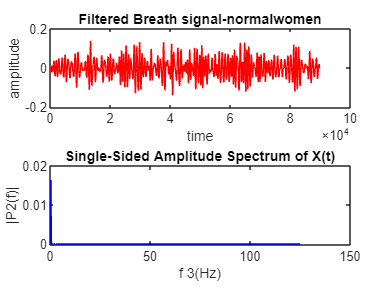


figure(4);
subplot(2,1,1);
plot(y2,'r'); %%non-preg
title('Filtered Breath signal-normalwomen')             
xlabel('time')
ylabel('amplitude')
Y3 = fft(y2);
P31 = abs(Y3/L);    
P21 = P31(1:L/2+1);
P21(2:end-1) = 2*P21(2:end-1);
f3 = fs*(0:(L/2))/L;
subplot(2,1,2);
plot(f3,P21,'b')  
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f 3(Hz)')
ylabel('|P2(f)|')

[~,I] = max(abs(P21));
freq=f3(I);
fprintf('Maximum occurs at %3.2f Hz.\n',f3(I));

Maximum occurs at 0.33 Hz.


 fprintf('BR =%3.2f bpm.\n ',f3(I)*60);

BR =19.83 bpm.
 

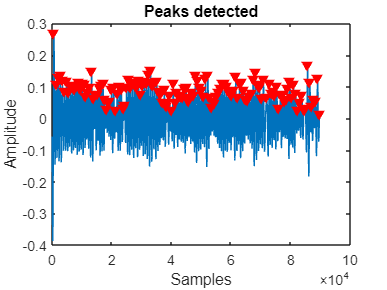



%% Breath rate variability:
[pks locs]= findpeaks(y1,'MinPeakHeight',0.01,'MinPeakDistance',80); %pregnant women
figure(5)
plot(y1);
hold on;
plot(locs,y1(locs),'rv','MarkerFaceColor','r');
xlabel('Samples');
ylabel('Amplitude');
title('Peaks detected'); 

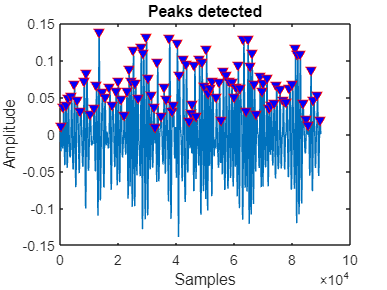

preglocs=locs/fs;
preglocs1=diff(preglocs)/10;
preglocs_BR = preglocs1*60;

[pks_1 locs_1]= findpeaks(y2,'MinPeakHeight',0.01,'MinPeakDistance',80); %nonpregnant women
figure(6)
plot(y2);
hold on;
plot(locs_1,y2(locs_1),'rv','MarkerFaceColor','b');
xlabel('Samples');
ylabel('Amplitude');
title('Peaks detected'); 

nonpreglocs_1=locs_1/fs;
nonpreglocs_1=diff(nonpreglocs_1)/10;
nonpreglocs_BR = nonpreglocs_1*60;

%%Standard Deviation
Preg_SD = std(preglocs1);
NonPreg_SD = std(nonpreglocs_1);

%%Root mean square of successive differences
Preg_RMSSD = rms(preglocs_BR);
NonPreg_RMSSD = rms(nonpreglocs_BR);

%%BRV(100%)
PregBRV =( (Preg_SD/Preg_RMSSD)*100)*100;
NonPregBRV =( (NonPreg_SD/NonPreg_RMSSD)*100)*100;


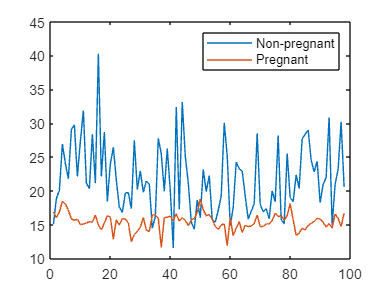

figure;
plot(nonpreglocs_BR, 'DisplayName', 'Non-pregnant');
hold on;
plot(preglocs_BR(1:98), 'DisplayName', 'Pregnant');
legend('show');